AChmut_datapath=["/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"
                 ]

AChmut_datapath = 5×1 string array
    "/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"



ExperimentNames=["20220422_112_AChmtut_SW_001",
                 "20220206_112_8_AChMut_SW_001",
                 "20220425_109_AChmut_SW_001",
                 "20220207_109_AChMut_SW_001",
                 "20220712_PM29_111_Achmut_001"
                 ]

ExperimentNames = 5×1 string array
    "20220422_112_AChmtut_SW_001"
    "20220206_112_8_AChMut_SW_001"
    "20220425_109_AChmut_SW_001"
    "20220207_109_AChMut_SW_001"
    "20220712_PM29_111_Achmut_001"



All_data_path = '/Volumes/PcSSDA/AChMut/'

All_data_path = '/Volumes/PcSSDA/AChMut/'

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


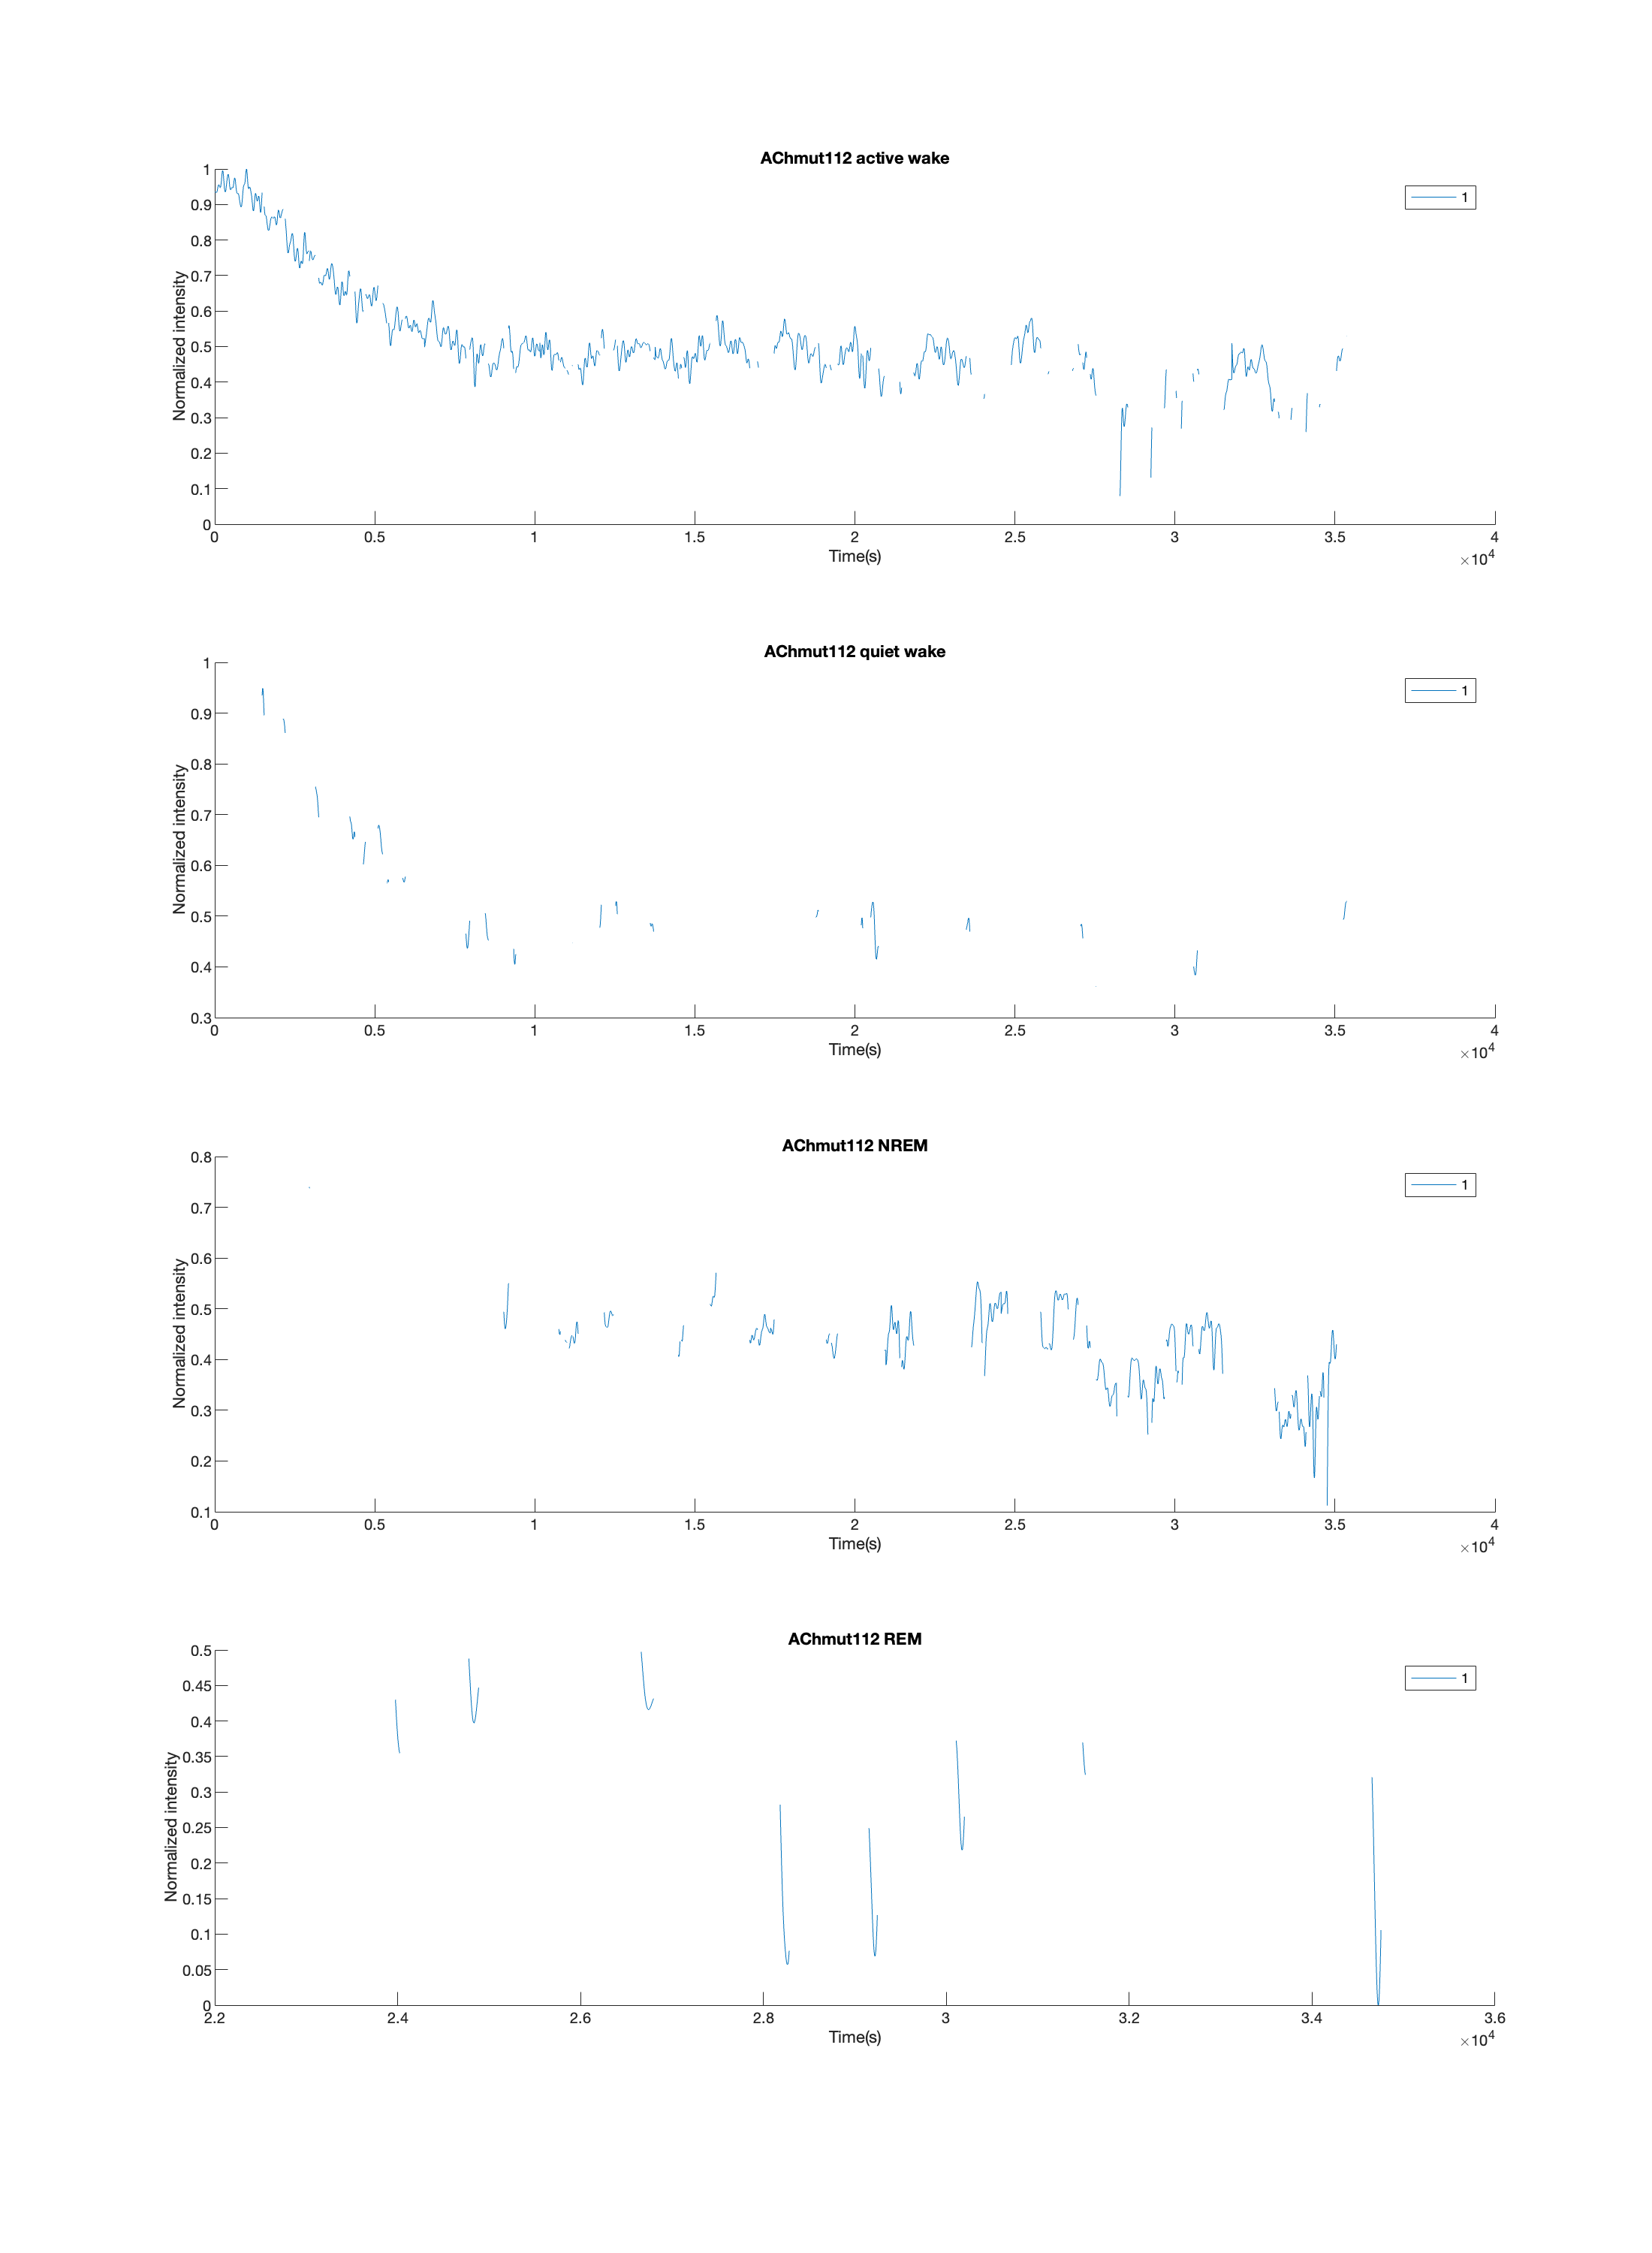

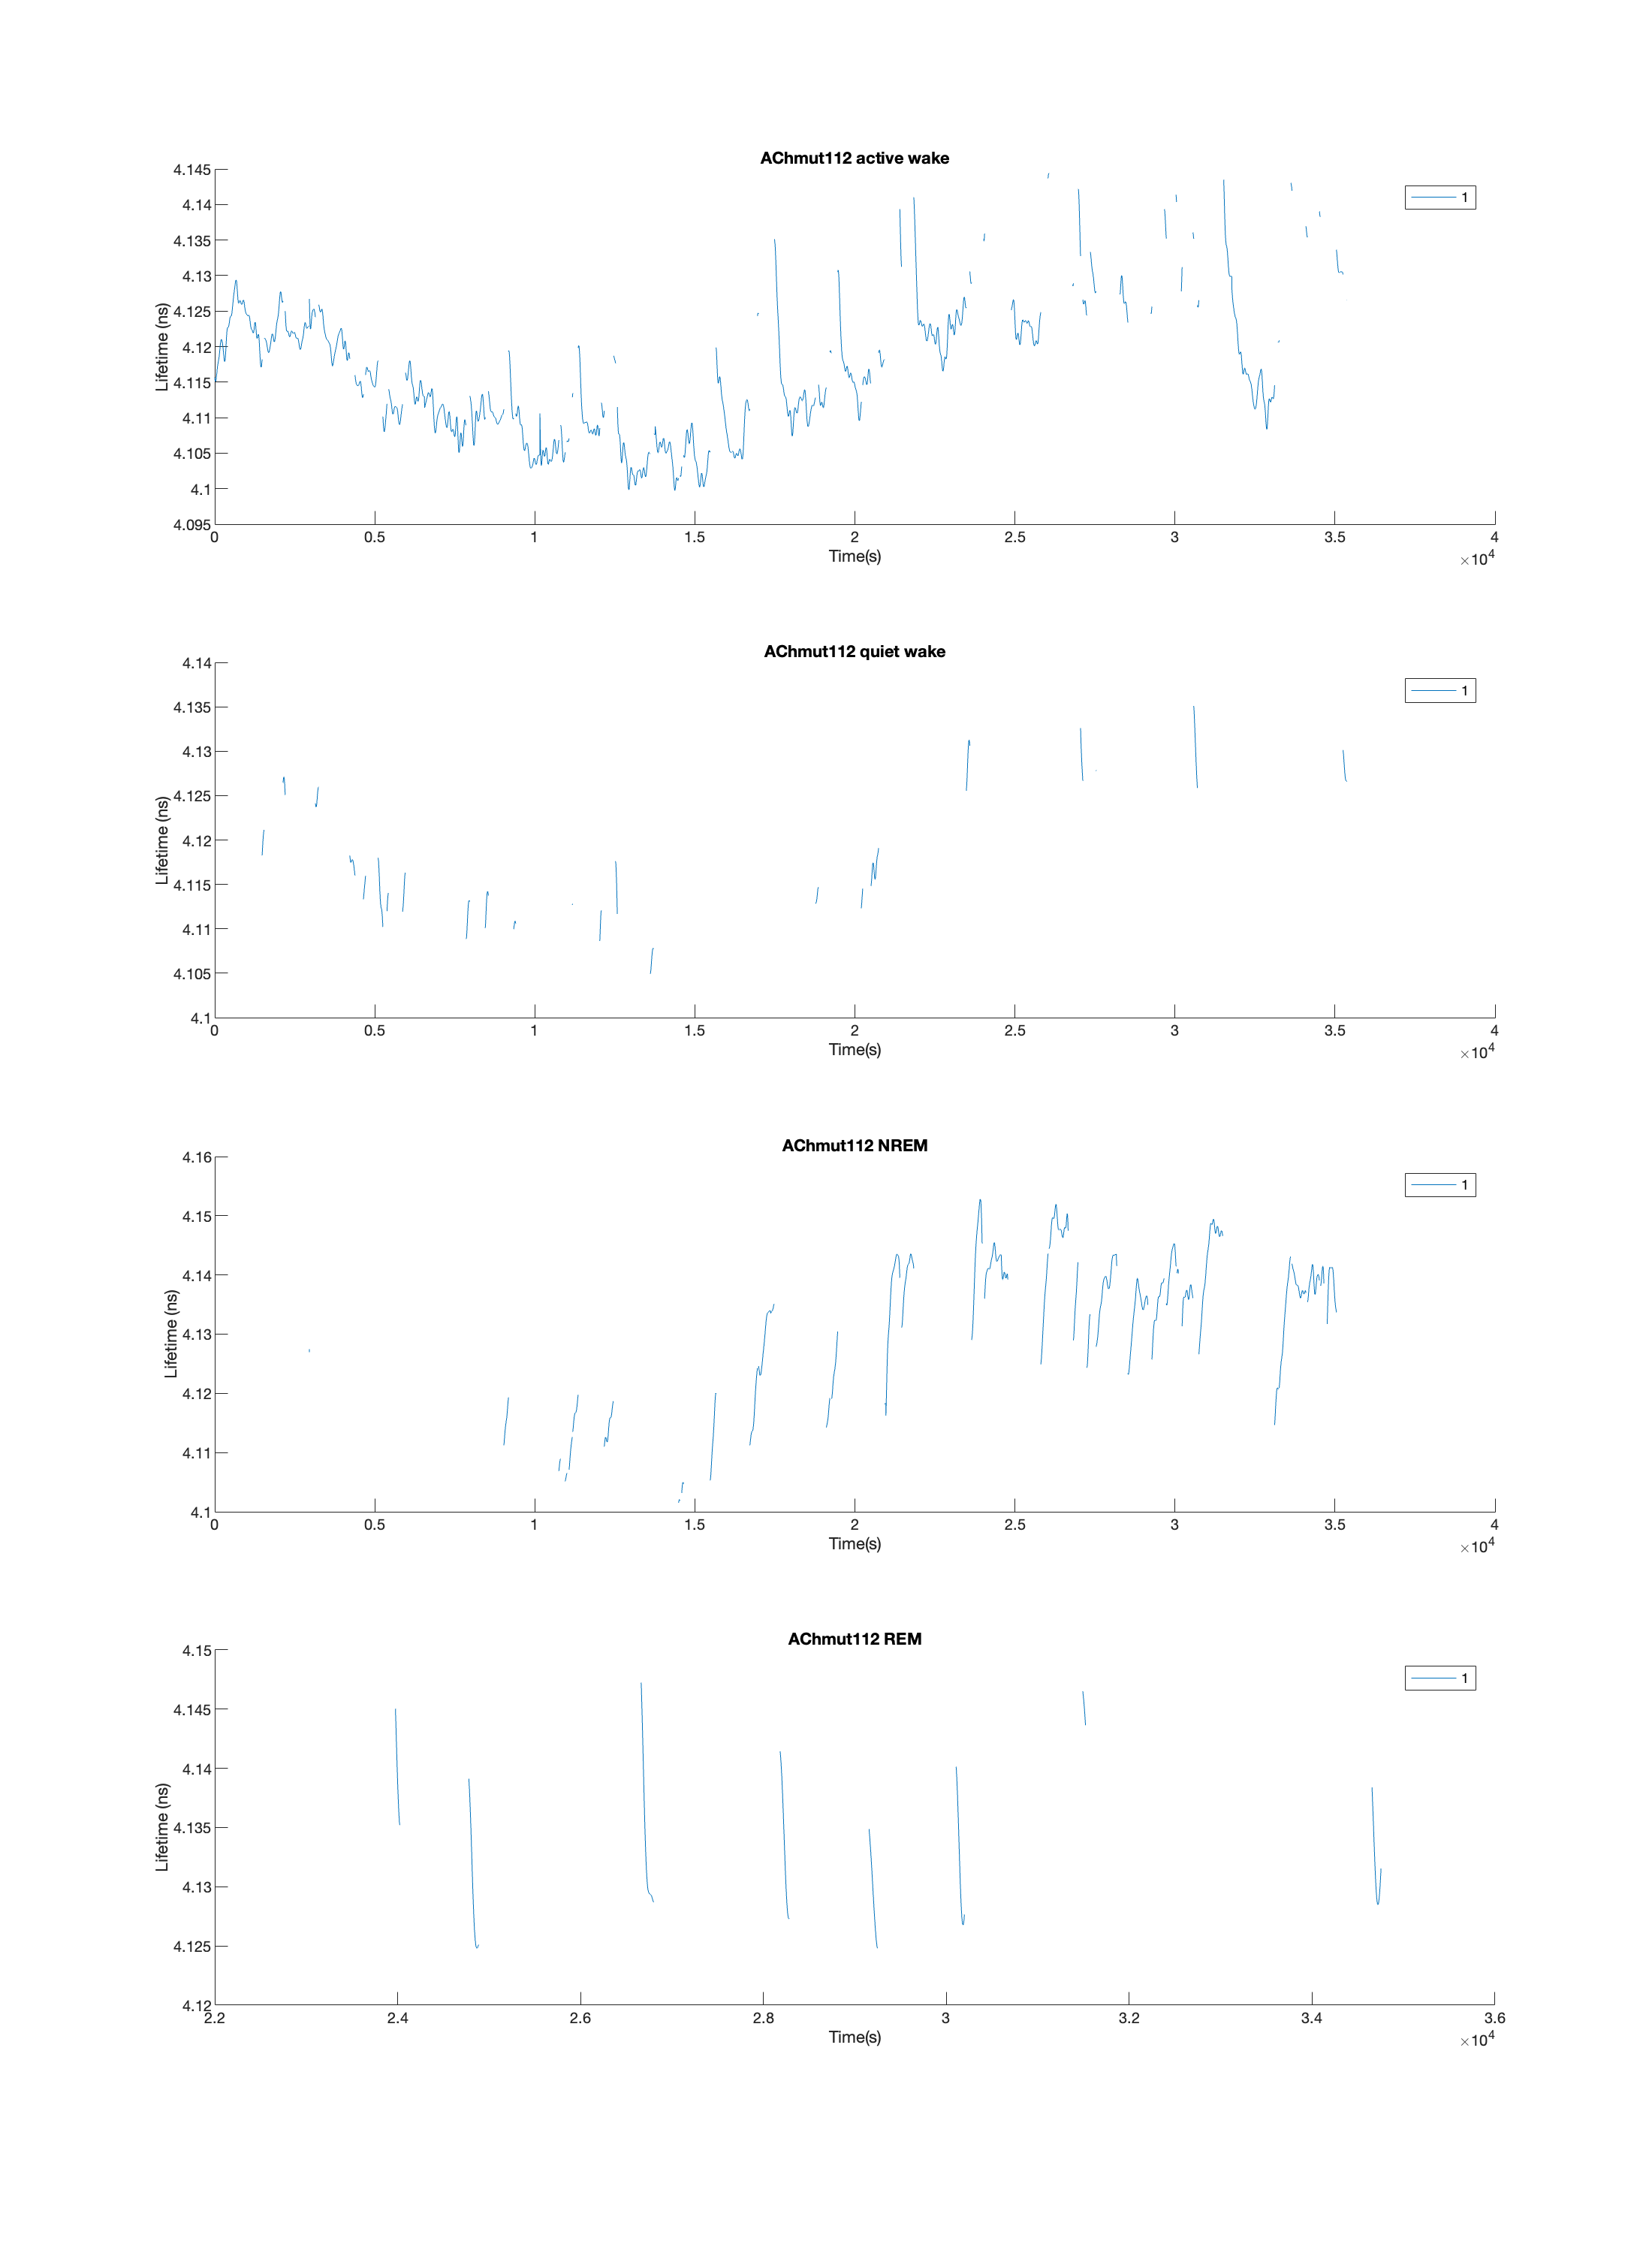

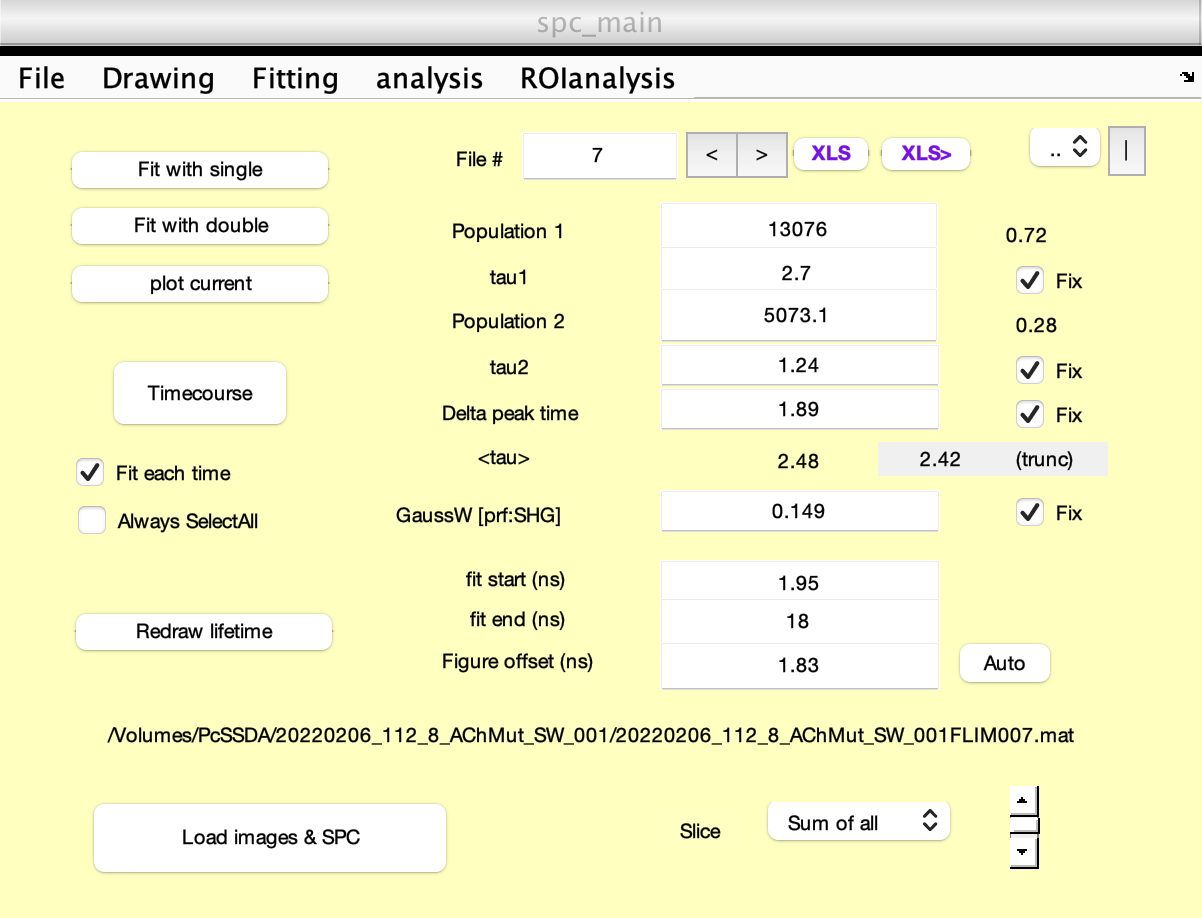

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


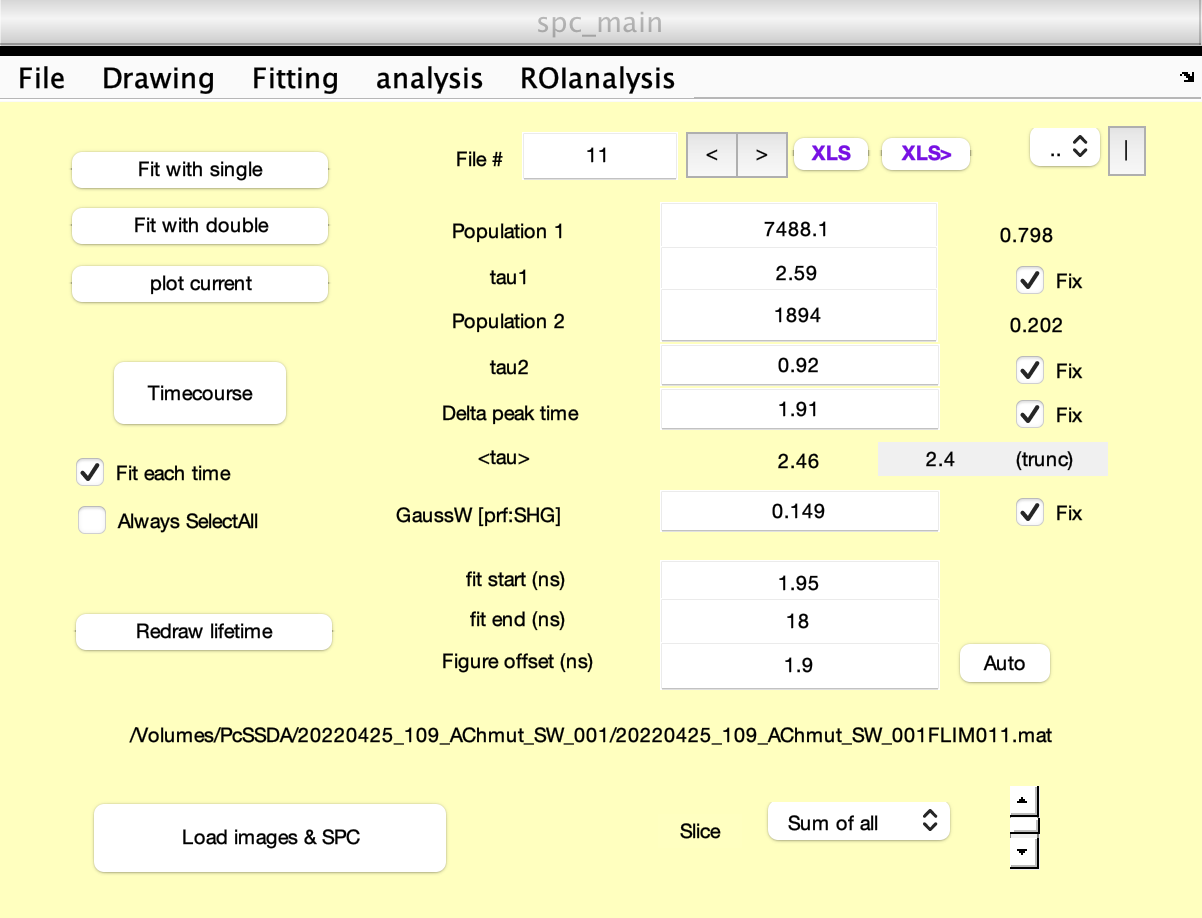

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


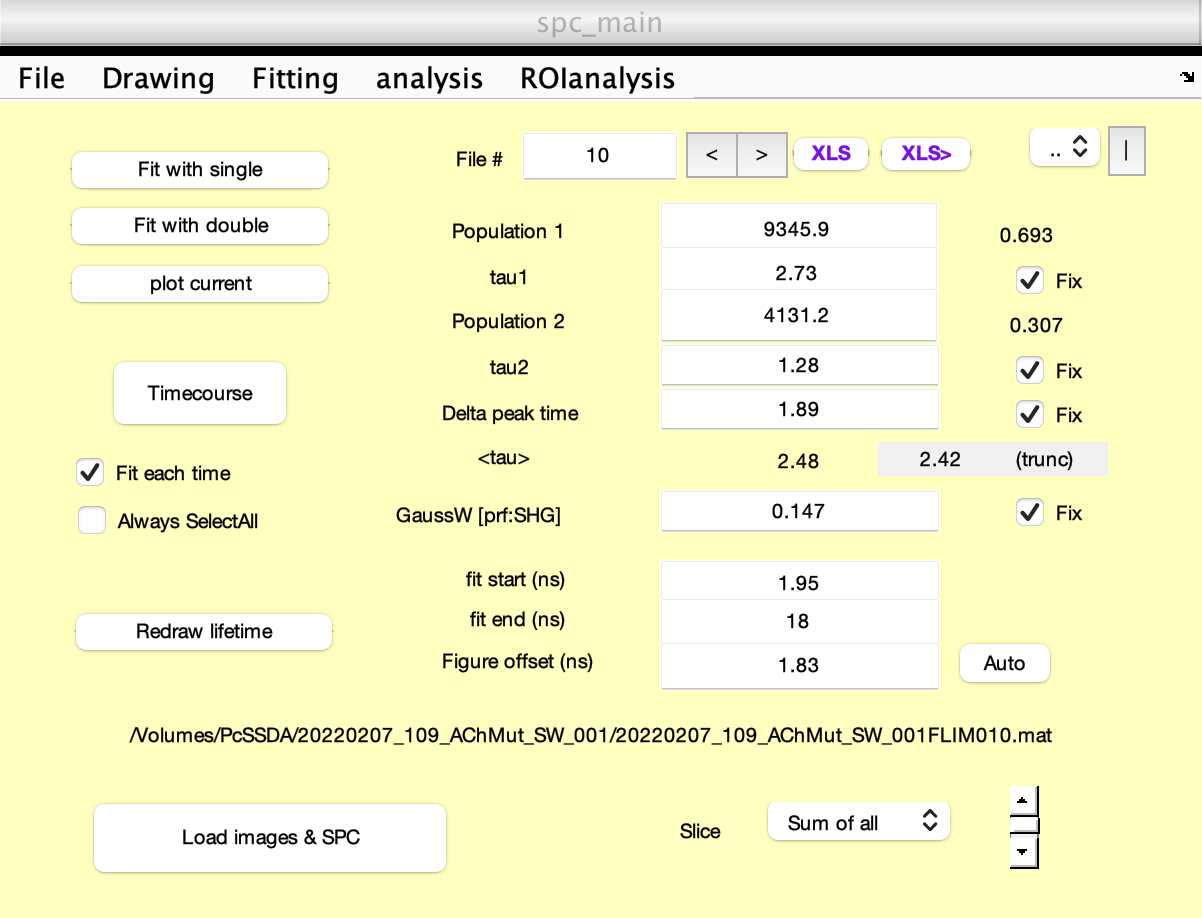

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


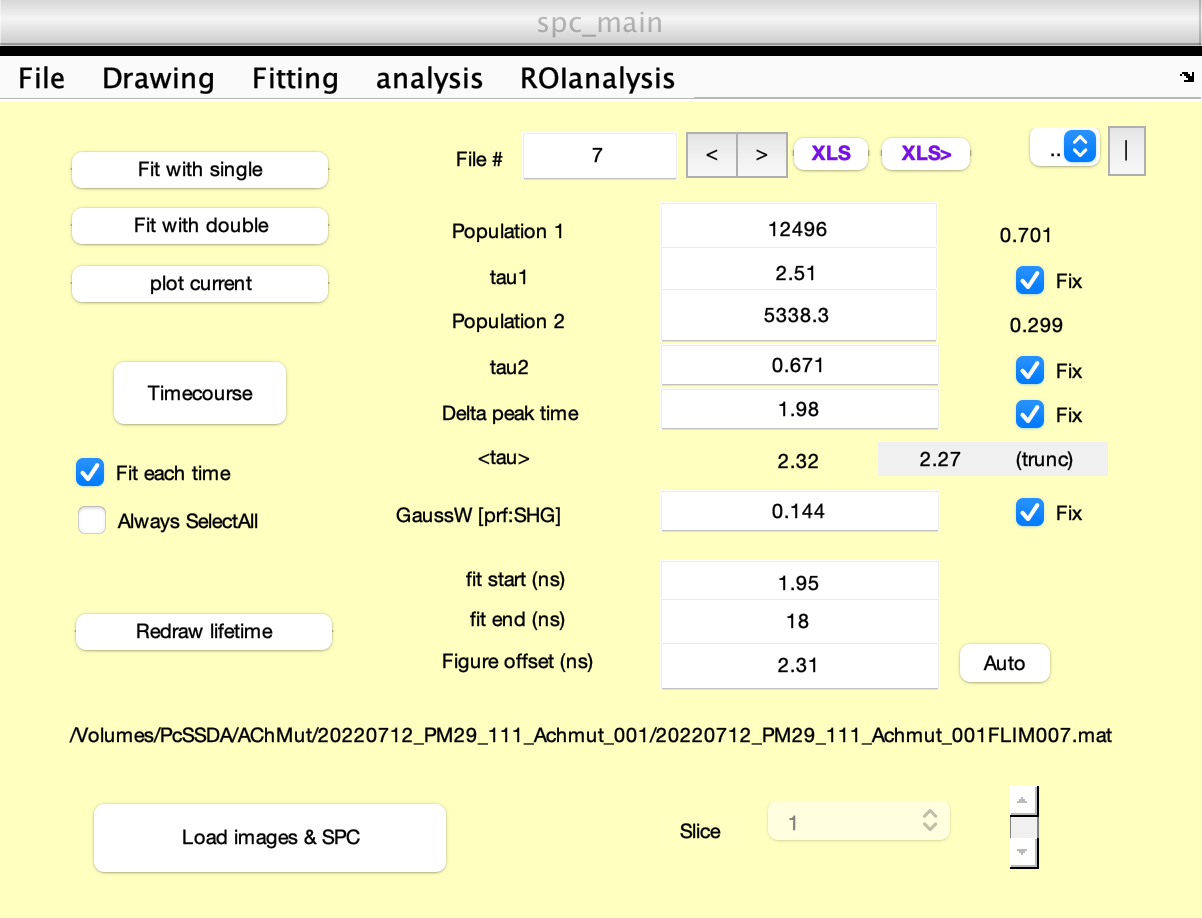

figure
for ii=1:5
    cd(convertStringsToChars(AChmut_datapath(ii)))
    load('FLP_analysis.mat');

    subplot(3,2,ii)
    yyaxis left
    plot(intensity_all_darkonly)
    ylabel('intensity')
    yyaxis right
    plot(tau_empTrunc_all_darkonly)
    ylabel('Lifetime(ns)')
    legend('Intensity','Lifetime')
    title(ExperimentNames(ii))

end

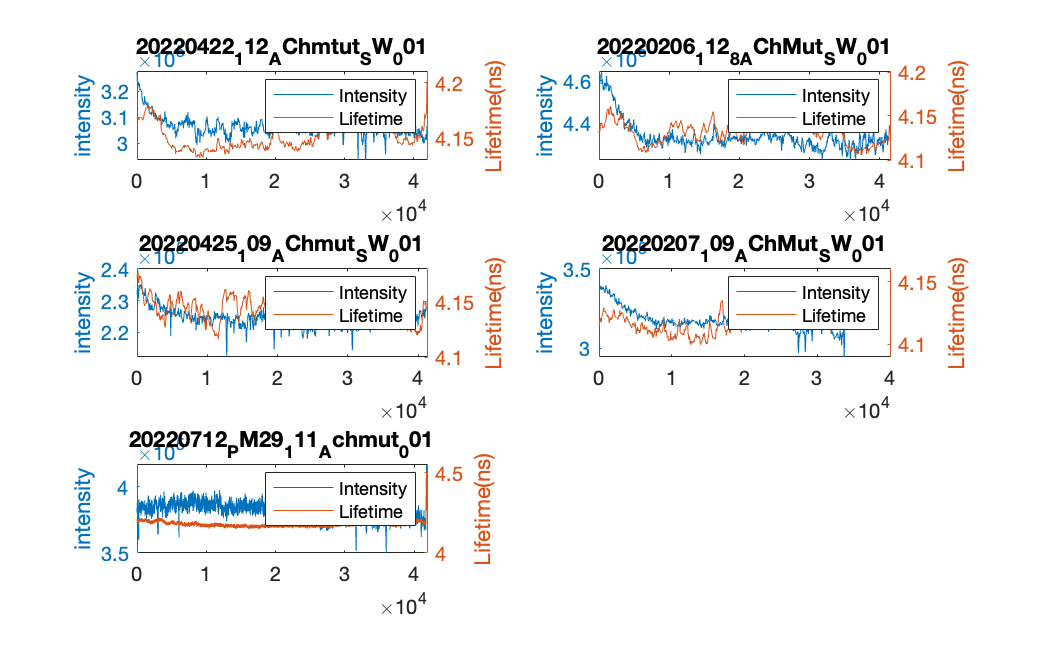

set(gcf, 'Position', get(0, 'Screensize'));
saveas(gcf,[All_data_path,'Intensity_lifetime_drifting.fig'])
saveas(gcf,[All_data_path,'Intensity_lifetime_drifting.png'])

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


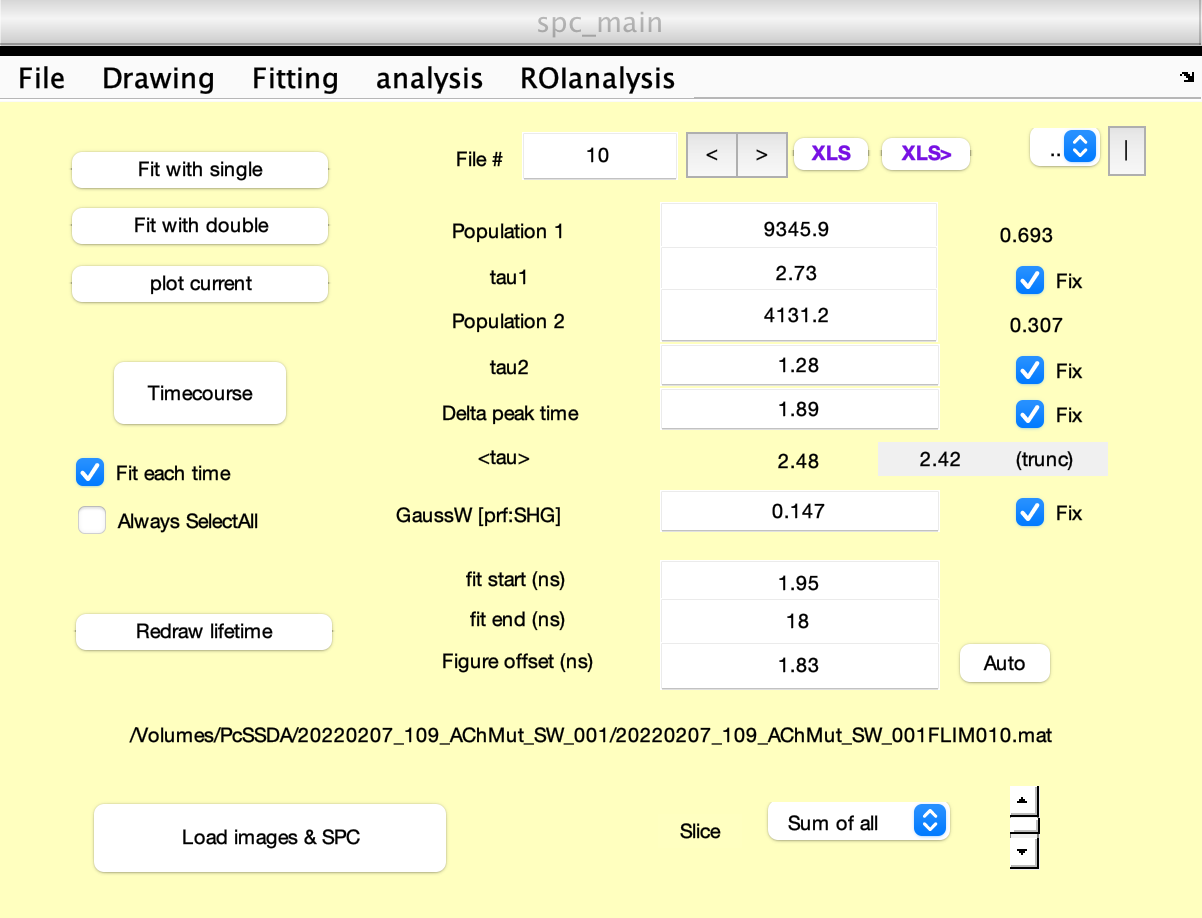

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


figure
for ii=1:5
    cd(convertStringsToChars(AChmut_datapath(ii)))
    load('FLP_analysis.mat');
    lifetime_histograms_all_darkonly = lifetime_histograms_all(:,dark_acqs);
    maxs=max(lifetime_histograms_all(:,dark_acqs));
    histograms_norm = lifetime_histograms_all_darkonly./maxs;
    semilogy(mean(transpose(histograms_norm)))
    hold on
end

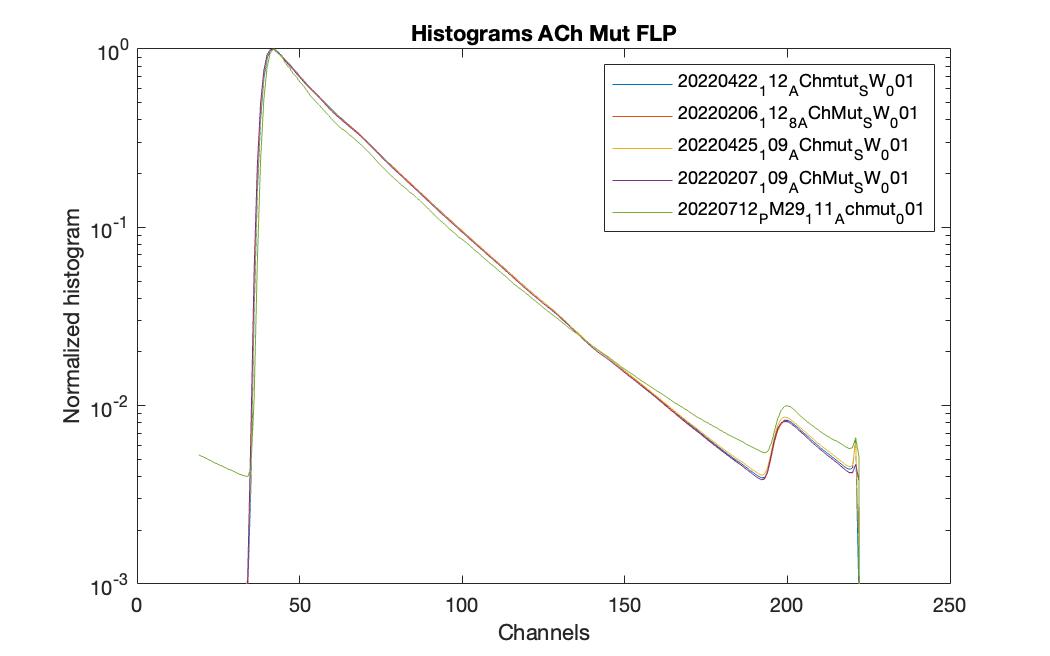


ylim([10e-4,1])
ylabel('Normalized histogram')
xlabel('Channels')
legend(ExperimentNames)
title('Histograms ACh Mut FLP')
set(gcf, 'Position', get(0, 'Screensize'));
saveas(gcf,[All_data_path,'Histograms.fig'])
saveas(gcf,[All_data_path,'Histograms.png'])
hold off

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


% plot the histogram of a NREM acqn from dark phase
hist_peaks = [];

figure
for ii = 1:5
    cd(convertStringsToChars(AChmut_datapath(ii)))
    load('FLP_analysis.mat');
    lifetime_histograms_all_darkonly = lifetime_histograms_all(:,dark_acqs);
    dark_NREM_index = find(states_for_time_all_dark == 2);
    histogram_NREM = lifetime_histograms_all_darkonly(:,dark_NREM_index(end-100));
    hist_peak = find(histogram_NREM == max(histogram_NREM));
    hist_peaks = [hist_peaks hist_peak];
    histogram_NREM_norm = histogram_NREM/max(histogram_NREM);
    semilogy(histogram_NREM_norm);
    hold on
    eval(['histogram_NREM_',num2str(ii), '=histogram_NREM;'])
    eval(['histogram_NREM_norm_',num2str(ii), '=histogram_NREM_norm;'])
    
end

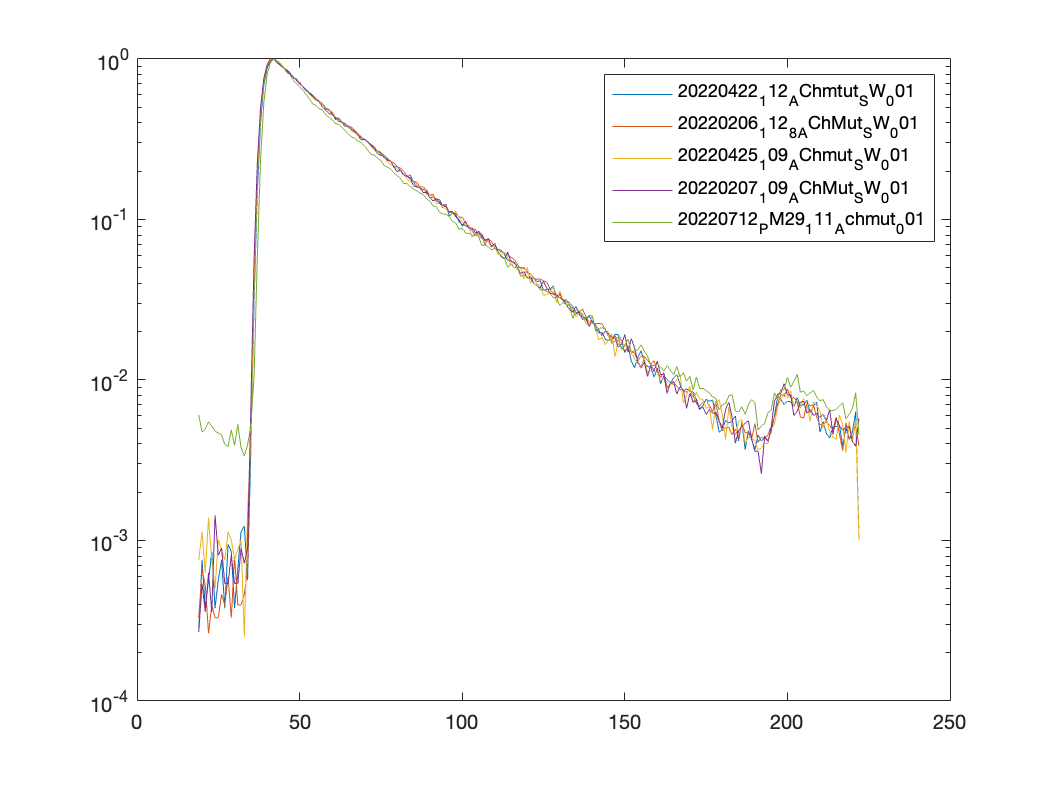

legend(ExperimentNames)
hold off

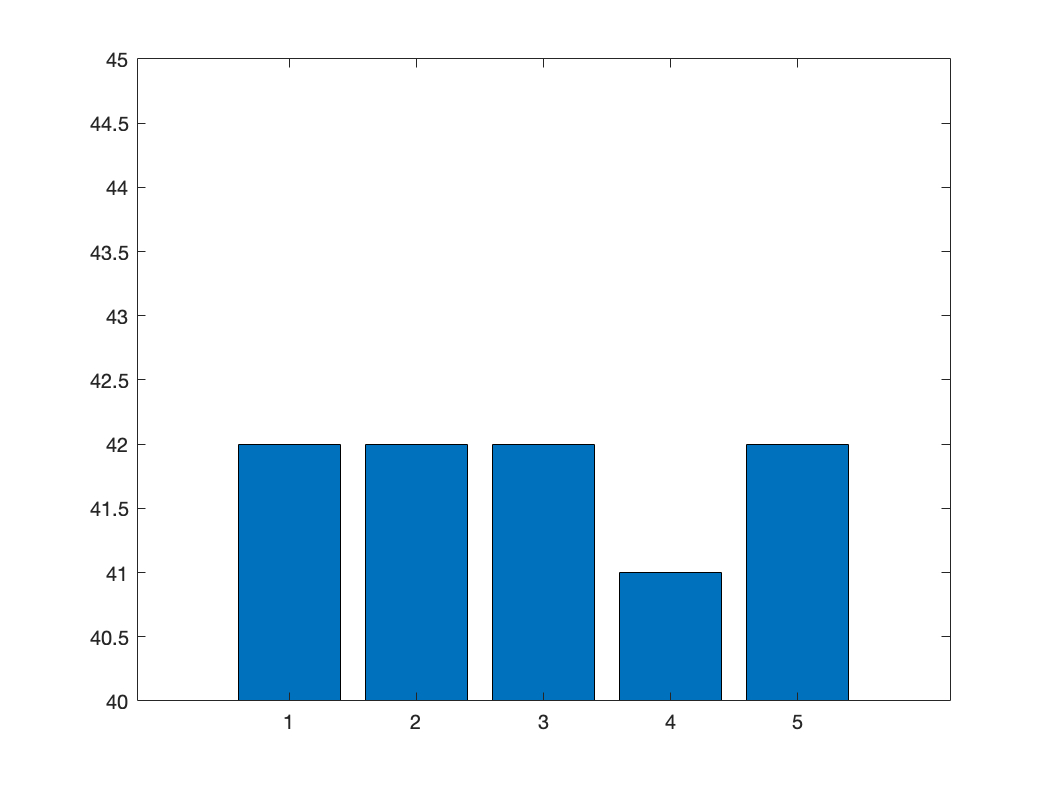

figure
bar(hist_peaks)
ylim([40 45])

prf_paths = ...
    ["/Volumes/PcSSDA/prf/20220206_IRFTest",...
    "/Volumes/PcSSDA/prf/20220404_fiber_twist_prf_001",...
    "/Volumes/PcSSDA/prf/20220616_prftest"];

prf_dates = ["0206", "0404", "0616"];

prf_acqns = [9 9 6]

prf_acqns =      9     9     6



prf_baseName = ...
    ["20220206_IRFTest",...
    "20220404_fiber_twist_prf_001",...
    "20220616_prftest"];

figure
prf_peaks = [];
annotation_options = {'\leftarrow', '\rightarrow', ''}

annotation_options = 1×3 cell array
    {'\leftarrow'}    {'\rightarrow'}    {0×0 char}


for ii = 1:3
    cd(convertStringsToChars(prf_paths(ii)))
    prf_file = [convertStringsToChars(prf_baseName(ii)), 'FLIM00', num2str(prf_acqns(ii)), '.mat']
    load(prf_file)
    prf_hist = spcSave.lifetimes{1};
    prf_hist_norm = prf_hist/max(prf_hist);
    prf_peak = find(prf_hist == max(prf_hist));
    prf_peaks = [prf_peaks prf_peak];
    prf_peaks_str{ii} = num2str(prf_peak);
    semilogy(prf_hist_norm)
    text(prf_peak,prf_hist_norm(prf_peak), [annotation_options{ii}, num2str(prf_peak)])
    hold on
end

prf_file = '20220206_IRFTestFLIM009.mat'

prf_file = '20220404_fiber_twist_prf_001FLIM009.mat'

prf_file = '20220616_prftestFLIM006.mat'

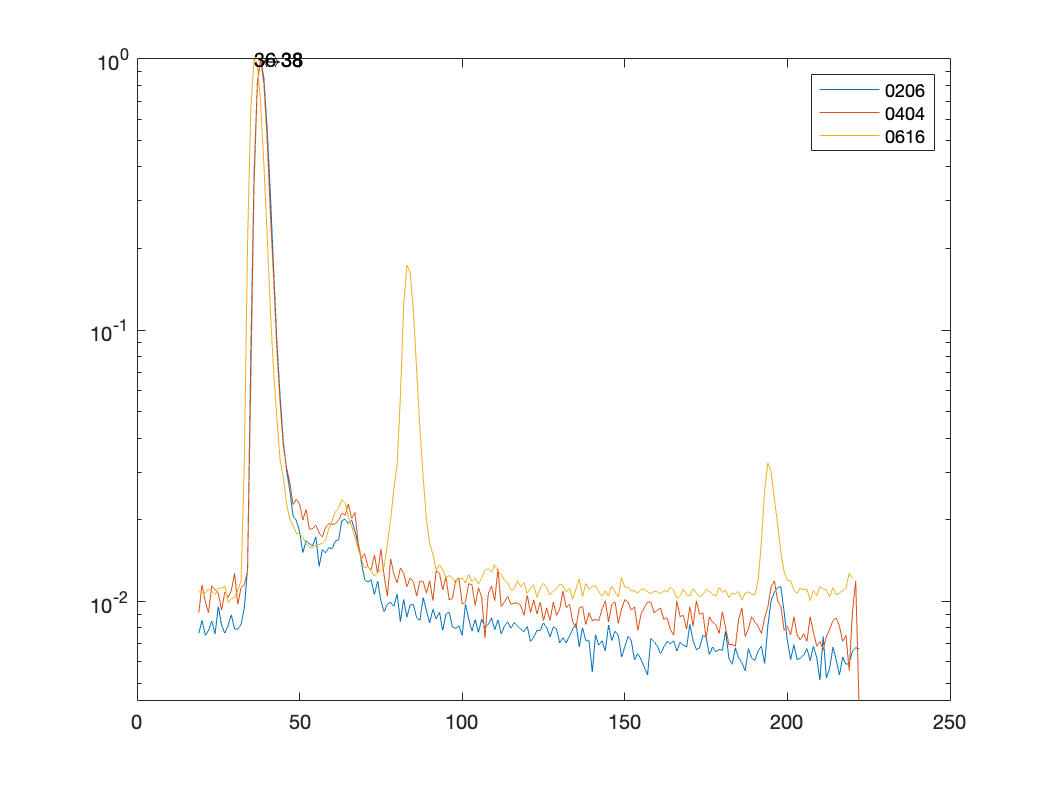


legend(prf_dates)
hold off

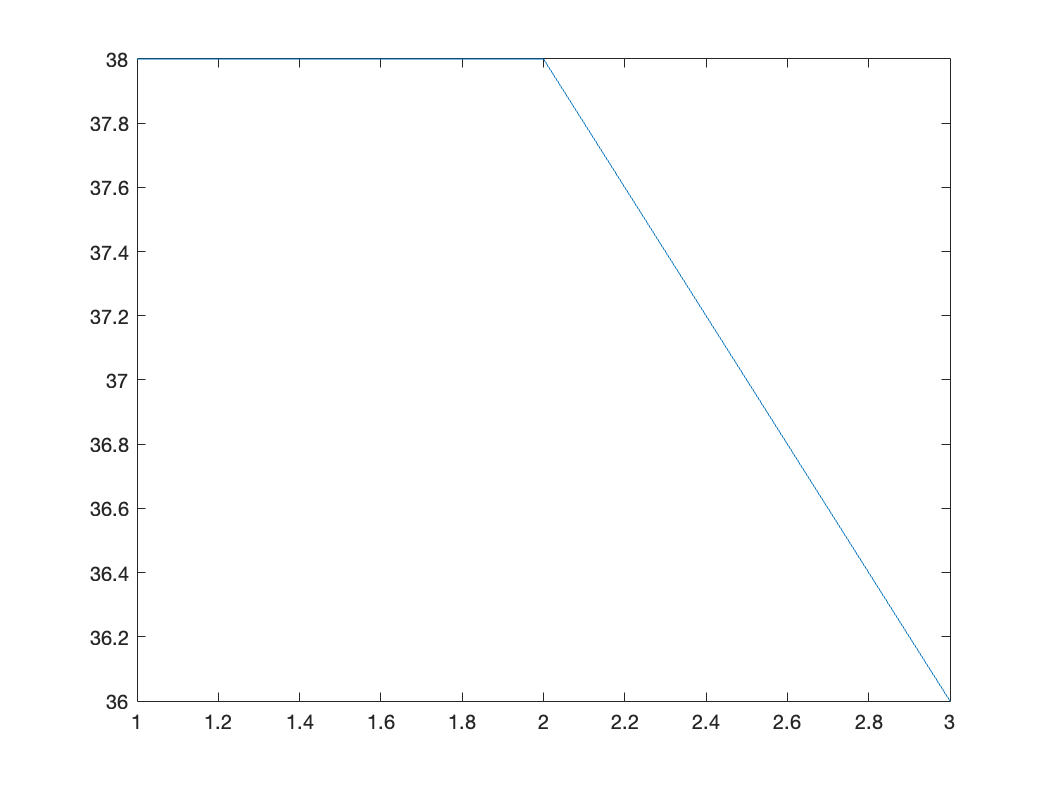

figure
plot(prf_peaks)

ii = 5

ii = 5

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


cd(convertStringsToChars(AChmut_datapath(ii)))
load('FLP_analysis.mat');

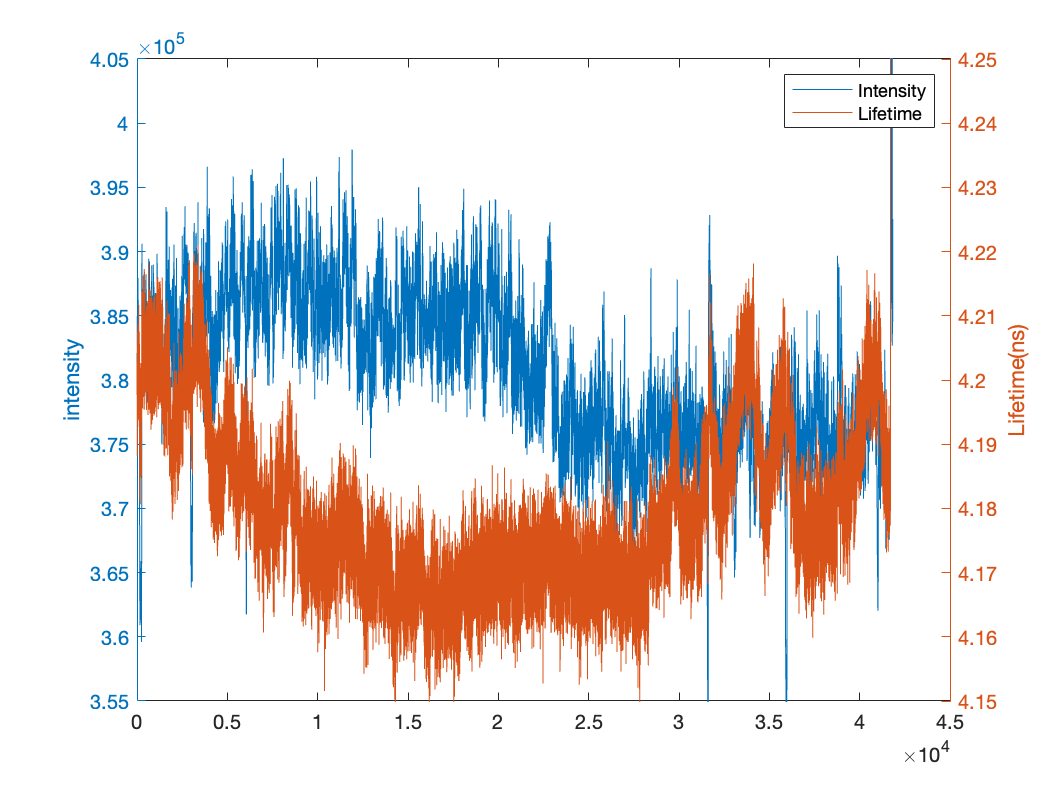

figure
yyaxis left
plot(intensity_all_darkonly)
ylim([355000 405000])
ylabel('intensity')
yyaxis right
plot(tau_empTrunc_all_darkonly)
ylim([4.15 4.25])
ylabel('Lifetime(ns)')
legend('Intensity','Lifetime')